# PROCESSING AM SR

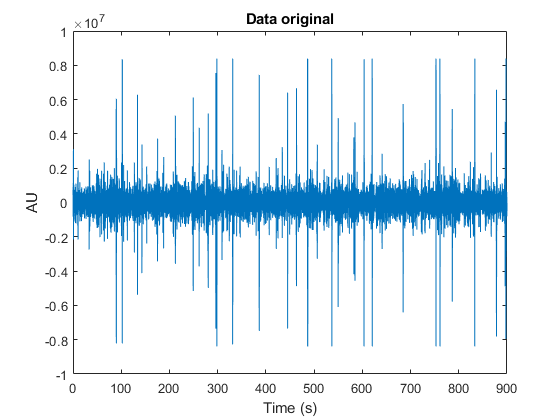

if (exist("data","var") == 0)
    data = (load("c_2013_11_16_04.dat"))';
end
fs = 187;
ts = 1/187;
tx = linspace(0,length(data) * ts, length(data));
plot(tx, data)
title("Data original");
ylabel("AU");

xlabel("Time (s)");

**Welch transformation with window length of 1870**

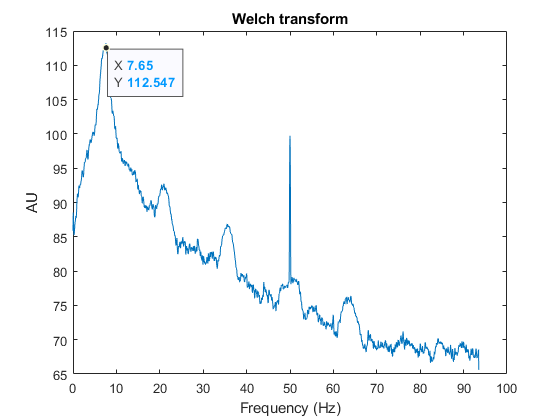

y_welch = SR_peak_welch(data, fs, 1870, 0);
f = linspace(0,fs/2,length(y_welch));
plot(f,y_welch);
title("Welch transform");
ylabel("AU");
xlabel("Frequency (Hz)");


data_filtered = preprocess_2hz(data,tx);

Unrecognized function or variable 'preprocess_2hz'.

plot(tx, data_filtered)
title("Data filtered with 2Hz BW");
ylabel("AU");
xlabel("Time (s)");
data_filtered_fixed = data_filtered;
data_filtered_fixed(data_filtered_fixed < 0) = 0;
plot(tx, data_filtered_fixed);
title("Data filtered only positive");
ylabel("AU");
xlabel("Time (s)");
%data_envelope = preprocess_envelope(data_filtered_fixed);
data_envelope = envelop_to_cut(data,tx);

plot(tx, data_envelope,'b', tx, data_filtered_fixed,'r',tx,data);
xlim([142 144])
ylim([-3e5 2.7e6])
title("Data envelope ");
ylabel("AU");
xlabel("Time (s)");
% Find local minima
%minIndices = islocalmin(data_envelope,'FlatSelection','first','MinSeparation',round(0.1 * fs));
minIndices = islocalmin(data_envelope*1e-6,'MinProminence',0.5,'FlatSelection','first','MinSeparation',round(0.1 * fs));
data_filtered_fixed = data;
% Visualize results
clf
plot(data_filtered_fixed,'Color',[109 185 226]/255,'DisplayName','Input data')
hold on

plot(data_envelope);
% Plot local minima
h1 = plot(find(minIndices),data_envelope(minIndices),'v','Color',[237 177 32]/255,...
    'MarkerFaceColor',[237 177 32]/255,'DisplayName','Local minima');
title(['Number of extrema: ' num2str(nnz(minIndices))])
hold off
legend


%xlim([42947 44119])
%ylim([-243030 1628647])
set(gcf,'position', [10,10, 1500,700])
xlim([26000 30000])
ylim([-3e5 2.7e6])


data_filter_real = preprocess(data,tx);

fl3 = 300;
[up3,lo3] = envelope(data_filter_real,fl3,'analytic');


min_time_vector = tx(minIndices);
min_index = find(minIndices);
for i = 1:(length(min_index)-1 )
    select_index = [min_index(i):min_index(i+1)];
    AM_SR_peak_vector(i) = AM_SR_peak(data_envelope(select_index),min_index(i), up3(select_index), data(select_index));
    fitheilder = AM_SR_peak_vector(i).fit_heilder;
end


AM_SR_peak_vector_no_qburst = AM_SR_peak_vector([AM_SR_peak_vector.max_value] < 2);

fit_max_values([AM_SR_peak_vector_no_qburst.max_value])
title("Distribution of max value");

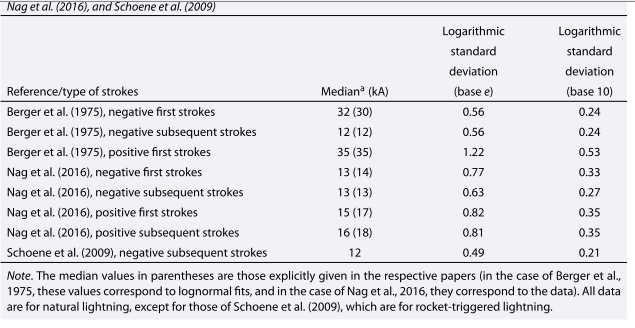

subplot(1,3,1);
fit_max_values([AM_SR_peak_vector_no_qburst.duration_simple])
title("DIstribution and fit with the simple duration algorithm");
%subplot(1,3,2);
%fit_max_values([AM_SR_peak_vector_no_qburst.duration_p2])
title("DIstribution and fit with the poly fit duration algorithm");
subplot(1,3,3);
fit_max_values([AM_SR_peak_vector_no_qburst.duration_p2])
title("Distribution and fit with the lorentzian fit algorithm");

scatter([AM_SR_peak_vector_no_qburst.duration_simple], [AM_SR_peak_vector_no_qburst.max_value])
subplot(3,1,1);
xlabel("duration poly 2")
ylabel("maximum value")
title("Scatter Maximum value vs duration simple");
scatter([AM_SR_peak_vector_no_qburst.duration_p2], [AM_SR_peak_vector_no_qburst.max_value ]);
subplot(3,1,2);
xlabel("duration poly 2")
ylabel("Increment")
title("Scatter Increment vs duration poly 2")
scatter([AM_SR_peak_vector_no_qburst.duration_lorentz], [AM_SR_peak_vector_no_qburst.max_value ])
subplot(3,1,3);
xlabel("duration Lorentzian algorithm")
ylabel("Increment")
title("Scatter Increment vs duration lorentzian algorithm")

## **Quantile Select**

[mean_duration_bw, std_duration_increment, mean_duration_decrement, std_duration_bw, number_of_quantiles, std_duration_decrement, mean_duration_increment] = get_mean_std_duration(AM_SR_peak_vector);

figure;
function_plot = @plot;
subplot(3,2,1);
function_plot(mean_duration_bw);
title("Quantile evolution of the mean duration")
ylabel("Time (s)")
xlabel("Quantile");


subplot(3,2,2);
function_plot(std_duration_bw);



title("Quantile evolution of the std duration")
ylabel("Time (s)")
xlabel("Quantile");

subplot(3,2,3);
function_plot(1:number_of_quantiles,mean_duration_increment);



title("Acumulated Quantile progresión of the mean(duration)")
ylabel("Time (s)")
xlabel("Quantile");
subplot(3,2,4);
function_plot(1:number_of_quantiles,std_duration_increment);


title("Acumulated Quantile progresión of the std(duration)")
subplot(3,2,5);
function_plot(number_of_quantiles:-1:1,mean_duration_decrement);

title(" Decremented Quantile progresión of the mean(duration)")
ylabel("Time (s)")
xlabel("Quantile");
subplot(3,2,6);
function_plot(number_of_quantiles:-1:1,std_duration_decrement);
title("Decremented Quantile progresión of the std(duration)")
ylabel("Time (s)")
xlabel("Quantile");

set(gcf,'position',[0,0,2000,1000]);

start_freq = 1;
end_freq = 48;
BW_1 = 0.1;
[SC_1,f_1] = extract_components(data,start_freq,end_freq,BW_1);
BW_2 = 0.2;
[SC_2,f_2] = extract_components(data,start_freq,end_freq,BW_2);

function_plot = @stem;
figure();

subplot(2,2,1);
function_plot(f_1,log10(SC_1));
ylim([min(log10(SC_1)), max(log10(SC_1))]);
[xc,lags] = xcorr((SC_1),length(SC_1),'biased');
lags_pos = lags(lags >= 0);
xc_pos = xc(lags >= 0);
title("Power of a selective band frequency with BW = 0.1");
xlabel("Frequency (Hz)");
ylabel("Power");

subplot(2,2,3);
function_plot(lags_pos*BW_1,log10(xc_pos));
ylim([min(log10(xc_pos)), max(log10(xc_pos))]);
title("Autocorr of power of a selective band frequency with BW = 0.1");
xlabel("Frequency (Hz)");
ylabel("Power");

subplot(2,2,2);
function_plot(f_2,log10(SC_2));
ylim([min(log10(SC_2)), max(log10(SC_2))]);
[xc,lags] = xcorr(SC_2,length(SC_2),'biased');
lags_pos = lags(lags >= 0);
xc_pos = xc(lags >= 0);
title("power of a selective band frequency with BW = 0.2");
xlabel("Frequency (Hz)");
ylabel("Power");


subplot(2,2,4);
function_plot(lags_pos*BW_2,log10(xc_pos));
ylim([min(log10(xc_pos)), max(log10(xc_pos))]);
title("Autocorr of power of a selective band frequency with BW = 0.1");
xlabel("Frequency (Hz)");
ylabel("Power");
set(gcf,'position',[0,0,2000,1000]);


function [mean_duration_bw, std_duration_increment, mean_duration_decrement, std_duration_bw, number_of_quantiles, std_duration_decrement, mean_duration_increment] = get_mean_std_duration(AM_SR_peak_vector)
number_of_quantiles = 50;
quantile_max_value = quantile([AM_SR_peak_vector.max_value],number_of_quantiles);
quantile_max_value = [0,quantile_max_value];

mean_duration_increment = zeros(1, number_of_quantiles);
std_duration_increment = zeros(1,number_of_quantiles);
mean_duration_decrement = zeros(1, number_of_quantiles);
std_duration_decrement = zeros(1,number_of_quantiles);
mean_duration_bw = zeros(1,number_of_quantiles);
std_duration_bw = zeros(1,number_of_quantiles);
for i = 1:(number_of_quantiles)
    AM_SR_peak_vector_low = AM_SR_peak_vector([AM_SR_peak_vector.max_value] < quantile_max_value(i+1));
    
    AM_SR_peak_vector_high = AM_SR_peak_vector([AM_SR_peak_vector.max_value] > quantile_max_value(number_of_quantiles - i + 1));
    
    AM_SR_peak_vector_bw = AM_SR_peak_vector(and([AM_SR_peak_vector.max_value] > quantile_max_value(i),[AM_SR_peak_vector.max_value] < quantile_max_value(i+1)));
    
    duration_low = [AM_SR_peak_vector_low.duration_lorentz];
    duration_high = [AM_SR_peak_vector_high.duration_lorentz];
    duration_bw = [AM_SR_peak_vector_bw.duration_lorentz];
    mean_duration_bw(i) = mean(duration_bw);
    std_duration_bw(i) = std(duration_bw);
    mean_duration_increment(i) = mean(duration_low);
    std_duration_increment(i) = std(duration_low);
    mean_duration_decrement(i) = mean(duration_high);
    std_duration_decrement(i) = std(duration_high);
end
end